close all;
clear;
mat2Load = "./cpd-gp-result/cpd-result-11.mat";
mat2Save = "./cpd-gp-result/gp-result-11.mat";


load(mat2Load, "np_srcX", "np_targetYs", "s", "sigma", "n", "eta");
gpReg = GP_Non_Rigid_Registration(np_srcX, s, sigma, n);
gpReg.compute_EigVals_EigFuncs_of_GP_K();

Finish computing eigVals and eigVecs of GP Registration
Low-rank approx. percentage of GP: 0.6980 



n_sample = length(np_targetYs);
targetYs = cell(1,n_sample);
for i = 1:n_sample
    targetYs{i} = double(np_targetYs{i})';
end
eta = double(eta);% normalization factor of alpha

deformedXs = zeros([gpReg.d, gpReg.N, n_sample]);
    
    
A = [];
b = [];
Aeq = [];
beq = [];
lb = [];
ub = [];
nonlcon = [];
options = optimoptions('fmincon','Display',"iter",'MaxFunctionEvaluations',3000);
srcX = gpReg.srcX;
GP_Mu = gpReg.GP_Mu;
phi_n = gpReg.phi_n;
lambda_n = gpReg.lambda_n;
alpha0 = zeros([n,1]);

num_thread = 4;
% parallel opt
parfor (idx = 1:n_sample, num_thread)
    alpha_opt = fmincon(@(alpha)GP_Non_Rigid_Registration.registration_loss(alpha,...
        srcX, targetYs{idx}, GP_Mu, phi_n, lambda_n, eta),...
        alpha0, A,b,Aeq,beq,lb,ub,nonlcon,options);

    deformedXs(:,:,idx) = GP_Non_Rigid_Registration.getDeformedX(alpha_opt, srcX, GP_Mu, phi_n, lambda_n);

    fprintf('The optimization of No.%d completed\n',idx);
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      22    5.479435e-01    0.000e+00    5.487e+00
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      22    6.662320e-01    0.000e+00    4.655e+00
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      22    4.817778e-01    0.000e+00    5.133e+00
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      22    3.851168e-01    0.000e+00    2.910e+00
    1      53    2.718697e-01    0.000e+00    2.584e+00    1.432e-01
    1      53    6.067807e-01    0.000e+00    4.507e+00    1.432e-01
    1      53    4.647673e-01    0.000e+00    6.791e+00    1.432e-01
    1      54    


% save params into .mat file
save(mat2Save, "deformedXs");

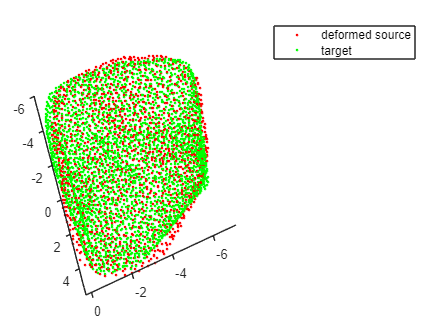

% visualization
close all;
hold on
j = 1;
dfmX = deformedXs(:,:,j);
Y = targetYs{j};
plot3(dfmX(1,:),dfmX(2,:),dfmX(3,:),'.','Color','r')
plot3(Y(1,:),Y(2,:),Y(3,:),'.','Color','g')
view(3)
legend('deformed source','target')
hold off